p_list(1) = load("results_p05.mat");
p_list(2) = load("results_p06.mat");
p_list(3) = load("results_p07.mat")

## Co-Adaptive Performance for Intended Movements: Paretic vs Non-Paretic

t2_rmse_avg_ctrl = [];
t2_rmse_avg_expl = [];

for i=1:length(p_list)
    t2_rmse_avg_ctrl = [t2_rmse_avg_ctrl; mean(p_list(i).participant_results(2).rmse.ctrl.int_a); mean(p_list(i).participant_results(2).rmse.ctrl.int_b)];
    t2_rmse_avg_expl = [t2_rmse_avg_expl; mean(p_list(i).participant_results(2).rmse.expl.int_a); mean(p_list(i).participant_results(2).rmse.expl.int_b)];
end

#### Histogram to look for outliers

tlo = tiledlayout(1,2);
nexttile
hist(t2_rmse_avg_ctrl)
isoutlier(t2_rmse_avg_ctrl, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


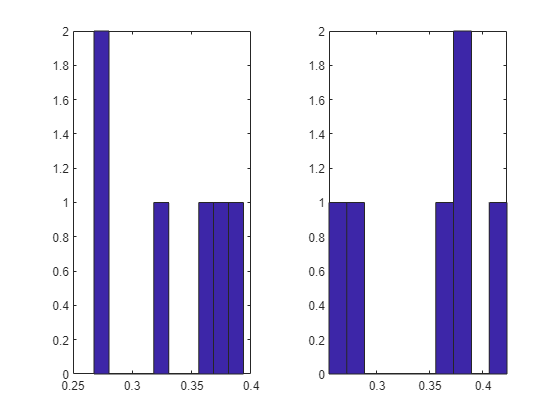

nexttile
hist(t2_rmse_avg_expl)

isoutlier(t2_rmse_avg_expl, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


#### AD Test for Parametric Data

Null Hypothesis: Data is from a population with normal distribution. 1: reject null hypothesis at 5% significance. 0: fail to reject null

adtest(t2_rmse_avg_ctrl)

ans = logical
   0


adtest(t2_rmse_avg_expl)

ans = logical
   0


#### Parametric 2-group Paired Comparison: Paretic vs Non-Paretic Performance for Intended Movements

Null Hypothesis: data in x-y comes from a normal distribution with a mean of zero. 0: fail to reject null

[h, p] = ttest(t2_rmse_avg_ctrl, t2_rmse_avg_expl)

h = 0

p = 0.5756


t2_mean_xpar_int = mean(t2_rmse_avg_ctrl)

t2_mean_xpar_int = 0.3329

t2_sem_xpar_int = std(t2_rmse_avg_ctrl)/sqrt(length(t2_rmse_avg_ctrl))

t2_sem_xpar_int = 0.0215

t2_mean_par_int = mean(t2_rmse_avg_expl)

t2_mean_par_int = 0.3486

t2_sem_par_int = std(t2_rmse_avg_expl)/sqrt(length(t2_rmse_avg_expl))

t2_sem_par_int = 0.0273

## Co-Adaptive Performance for Non-Intended Movements: Paretic vs Non-Paretic

t2_rmse_avg_ctrl = [];
t2_rmse_avg_expl = [];

for i=1:length(p_list)
    t2_rmse_avg_ctrl = [t2_rmse_avg_ctrl; mean(p_list(i).participant_results(2).rmse.ctrl.xint_a); mean(p_list(i).participant_results(2).rmse.ctrl.xint_b)];
    t2_rmse_avg_expl = [t2_rmse_avg_expl; mean(p_list(i).participant_results(2).rmse.expl.xint_a); mean(p_list(i).participant_results(2).rmse.expl.xint_b)];
end

#### Histogram to look for outliers

tlo = tiledlayout(1,2);
nexttile
hist(t2_rmse_avg_ctrl)
isoutlier(t2_rmse_avg_ctrl, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


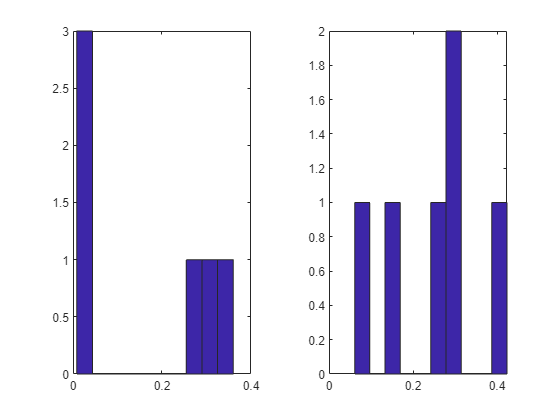

nexttile
hist(t2_rmse_avg_expl)

isoutlier(t2_rmse_avg_expl, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


#### AD Test for Parametric Data

Null Hypothesis: Data is from a population with normal distribution. 1: reject null hypothesis at 5% significance. 0: fail to reject null

adtest(t2_rmse_avg_ctrl)

ans = logical
   0


adtest(t2_rmse_avg_expl)

ans = logical
   0


#### Parametric 2-group Paired Comparison: Paretic vs Non-Paretic Performance for Non-Intended Movements

Null Hypothesis: data in x-y comes from a normal distribution with a mean of zero. 0: fail to reject null

[h, p] = ttest(t2_rmse_avg_ctrl, t2_rmse_avg_expl)

h = 0

p = 0.0805


t2_mean_xpar_xint = mean(t2_rmse_avg_ctrl)

t2_mean_xpar_xint = 0.1678

t2_sem_xpar_xint = std(t2_rmse_avg_ctrl)/sqrt(length(t2_rmse_avg_ctrl)) 

t2_sem_xpar_xint = 0.0652

t2_mean_par_xint = mean(t2_rmse_avg_expl)

t2_mean_par_xint = 0.2509

t2_sem_par_xint = std(t2_rmse_avg_expl)/sqrt(length(t2_rmse_avg_expl))

t2_sem_par_xint = 0.0513

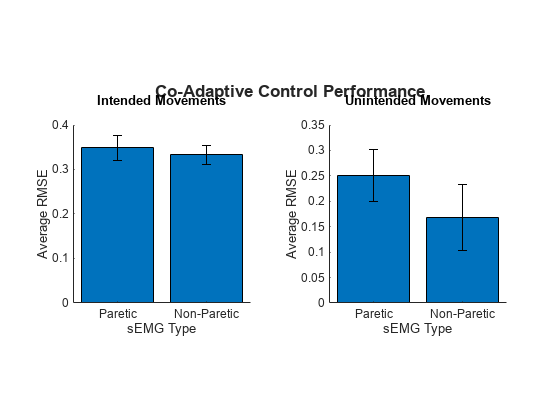



figure
tlo = tiledlayout(1,2);
nexttile
x=1:2;
data = [t2_mean_par_int t2_mean_xpar_int]';
errhigh = [t2_sem_par_int, t2_sem_xpar_int];
errlow  = errhigh;

bar(x,data)                

hold on

er = errorbar(x,data,errlow,errhigh);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off
box off
axis square

xticklabels({'Paretic', 'Non-Paretic'})
xlabel("sEMG Type")
ylabel('Average RMSE')
title({"Intended Movements",""})
nexttile
x=1:2;
data = [t2_mean_par_xint t2_mean_xpar_xint]';
errhigh = [t2_sem_par_xint, t2_sem_xpar_xint];
errlow  = errhigh;

bar(x,data)                

hold on

er = errorbar(x,data,errlow,errhigh);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off
box off
axis square

xticklabels({'Paretic', 'Non-Paretic'})
xlabel("sEMG Type")
ylabel('Average RMSE')
title({"Unintended Movements",""})
title(tlo, {"Co-Adaptive Control Performance",""}, FontWeight='bold')

## Paretic Performance for Intended Movements: Adaptive vs Non-Adaptive

t2_rmse_avg_expl = [];
t3_rmse_avg_expl = [];

for i=1:length(p_list)
    t2_rmse_avg_expl = [t2_rmse_avg_expl; mean(p_list(i).participant_results(2).rmse.expl.int_a); mean(p_list(i).participant_results(2).rmse.expl.int_b)];
    t3_rmse_avg_expl = [t3_rmse_avg_expl; mean(p_list(i).participant_results(3).rmse.expl.int_a); mean(p_list(i).participant_results(3).rmse.expl.int_b)];
end

#### Histogram to look for outliers

tlo = tiledlayout(1,2);
nexttile
hist(t2_rmse_avg_expl)
isoutlier(t2_rmse_avg_expl, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


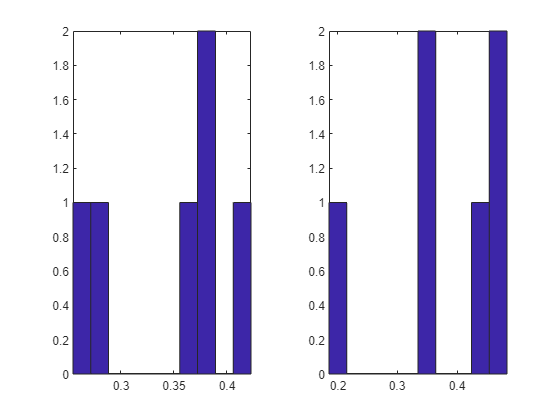

nexttile
hist(t3_rmse_avg_expl)

t3_outliers = isoutlier(t3_rmse_avg_expl, 'quartiles')

t3_outliers = 6×1 logical array
   0
   1
   0
   0
   0
   0


#### AD Test for Parametric Data

Null Hypothesis: Data is from a population with normal distribution. 1: reject null hypothesis at 5% significance. 0: fail to reject null

adtest(t2_rmse_avg_expl)

ans = logical
   0


adtest(t3_rmse_avg_expl)

ans = logical
   0


#### Parametric 2-group Paired Comparison: Adaptive vs Non-Adaptive Performance for Intended Movements

Null Hypothesis: data in x-y comes from a normal distribution with a mean of zero. 0: fail to reject null

[h, p] = ttest(t2_rmse_avg_expl(t3_outliers~=1), t3_rmse_avg_expl(t3_outliers~=1))

h = 1

p = 0.0350

t2_mean = mean(t2_rmse_avg_expl(t3_outliers~=1))

t2_mean = 0.3674

t2_sem = std(t2_rmse_avg_expl(t3_outliers~=1))/sqrt(length(t2_rmse_avg_expl(t3_outliers~=1)))

t2_sem = 0.0243

t3_mean = mean(t3_rmse_avg_expl(t3_outliers~=1))

t3_mean = 0.4212

t3_sem = std(t3_rmse_avg_expl(t3_outliers~=1))/sqrt(length(t3_rmse_avg_expl(t3_outliers~=1)))

t3_sem = 0.0266


figure
x=1:2

x =      1     2


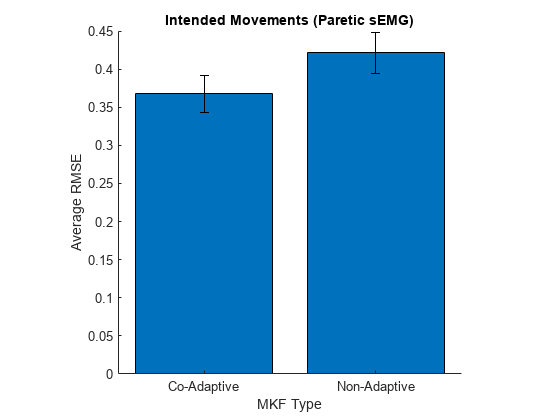

data = [t2_mean t3_mean]';
errhigh = [t2_sem, t3_sem];
errlow  = errhigh;

bar(x,data)                

hold on

er = errorbar(x,data,errlow,errhigh);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off
box off
axis square

xticklabels({'Co-Adaptive', 'Non-Adaptive'})
xlabel("MKF Type")
ylabel('Average RMSE')
title("Intended Movements (Paretic sEMG)")

## Paretic Performance for Non-Intended Movements: Adaptive vs Non-Adaptive

t2_rmse_avg_expl = [];
t3_rmse_avg_expl = [];

for i=1:length(p_list)
    t2_rmse_avg_expl = [t2_rmse_avg_expl; mean(p_list(i).participant_results(2).rmse.expl.xint_a); mean(p_list(i).participant_results(2).rmse.expl.xint_b)];
    t3_rmse_avg_expl = [t3_rmse_avg_expl; mean(p_list(i).participant_results(3).rmse.expl.xint_a); mean(p_list(i).participant_results(3).rmse.expl.xint_b)];
end

#### Histogram to look for outliers

tlo = tiledlayout(1,2);
nexttile
hist(t2_rmse_avg_expl)
isoutlier(t2_rmse_avg_expl, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


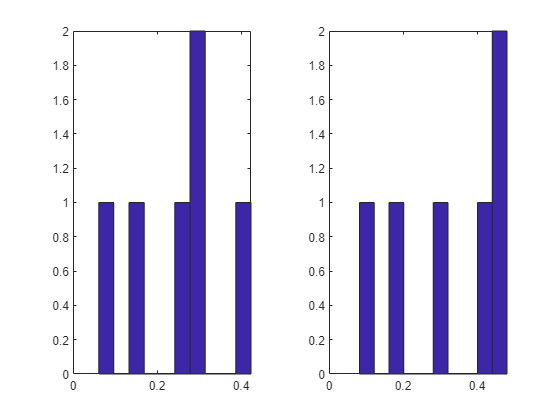

nexttile
hist(t3_rmse_avg_expl)

isoutlier(t3_rmse_avg_expl, 'quartiles')

ans = 6×1 logical array
   0
   0
   0
   0
   0
   0


#### AD Test for Parametric Data

Null Hypothesis: Data is from a population with normal distribution. 1: reject null hypothesis at 5% significance. 0: fail to reject null

adtest(t2_rmse_avg_expl)

ans = logical
   0


adtest(t3_rmse_avg_expl)

ans = logical
   0


#### Parametric 2-group Paired Comparison: Paretic vs Non-Paretic Performance for Intended Movements

Null Hypothesis: data in x-y comes from a normal distribution with a mean of zero. 0: fail to reject null

[h, p] = ttest(t2_rmse_avg_expl, t3_rmse_avg_expl)

h = 0

p = 0.0613

mean(t2_rmse_avg_expl)

ans = 0.2509

mean(t3_rmse_avg_expl)

ans = 0.3294